# Lymphoma SVM Multi-Class Classifier

## Samuel Ndirangu 

Github: [https://github.com/SamNdirangu/](https://github.com/SamNdirangu/)

LinkedIn: [https://www.linkedin.com/in/samndirangu](https://www.linkedin.com/in/samndirangu)

Date: 29/04/2019

**Introduction**

This dataset features 148 samples each with 18 features. This dataset was introduced to train models to detect 3 cases within a lymphogram. Samples are classified into four classes; normal, malignant, metastases and fibrosis. 

**References and Dataset source ** 

I. Kononenko and B. Cestnik (1988). UCI Machine Learning Repository [ [https://archive.ics.uci.edu/ml/datasets/Lymphography](https://archive.ics.uci.edu/ml/datasets/Lymphography) ]. Irvine, CA: University of California, School of Information and Computer Science. 

## Step 1: Dataset Preparation

Here we prepare our data so that it can be fed to the svm accordingly.

The data is first loaded from a given xlsx file and the necessry collumns extracted.

The data is then split into training and tests sets. One trains the svm the other is used to evaluate its accuracy perfomance.

## File Upload

%The prefix ckd refers to Chronic Kidney Disease
%Stores our file name and path
[file,path] = uigetfile({'*.xlsx';'*.csv'},'Select Data File')
selectedfile = fullfile(path,file);
opts = detectImportOptions(selectedfile); %Auto Load options for it
temp_data = readtable(selectedfile,opts); %Read the xlsx file and store it.
data = table2cell(temp_data); %Convert our table to a cell array

%Get our feature names
data_feature_names = cellstr(strrep(temp_data.Properties.VariableNames,'_',' '));

sample_no = size(data,1) %Get the number of all diagnosis
%Create our X and Y for SVM Training
X_temp = cell2mat(data(:,2:19));
%Our Y or dependent varible is in collumn 1
Y_temp = cell2mat(data(:,1));

rand_num = randperm(148); % Permutate numbers radomly, This works as shuffling our rows

X = X_temp(rand_num(1:end),:);
Y = Y_temp(rand_num(1:end),:);

%Get the number of features of X
noFeatures = size(X,2);

## Step 2: Preparing validation set out of trainin set (K-fold CV)

To reduce any underfitting or overfitting that may occur during testing the data is cross validated using K-Fold 5 times. The folds are stratified ensuring a uniform distribution of each class with in each fold further lowering any data bias that would have been present.

%Validate now the training set using Kfold 5 times
%A warning will however be thrown as one class is rare and cannot be present in all folds
CV = cvpartition(Y,'KFold',5,'Stratify',true);

## Step 3: Feature Ranking

This steps ranks our feature and creates a feature sets consisting  a given number of all the features from 1 feature to all features of the dataset

We use sequential FS and loop it a number of times equal to the number of features filling in a logical matrix of features.

opts = statset('display','iter','UseParallel',true); %Sets the display option
rng(5); %This sets our random state.

%We create a variable to store our template SVM option that the ecoc function will use to train multi-class SVM models
svmTemplate = templateSVM('Standardize',false,'KernelFunction','gaussian');

fun = @(train_data, train_labels, test_data, test_labels)...
    sum(predict(fitcecoc(train_data, train_labels,'Learners',svmTemplate), test_data) ~= test_labels);

%Rank our features using Sequential FS forward selection
%Inside history we store the ranking of features
[fs, history] = sequentialfs(fun, X, Y, 'cv', CV, 'options', opts,'nfeatures',noFeatures);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 13, criterion value 0.243243
Step 2, added column 17, criterion value 0.189189
Step 3, added column 11, criterion value 0.175676
Step 4, added column 6, criterion value 0.162162
Step 5, added column 1, criterion value 0.175676
Step 6, added column 7, criterion value 0.175676
Step 7, added column 8, criterion value 0.182432
Step 8, added column 9, criterion value 0.189189
Step 9, added column 2, criterion value 0.195946
Step 10, added column 15, criterion value 0.202703
Step 11, added column 5, criterion value 0.209459
Step 12, added column 3, criterion value 0.222973
Step 13, added column 16, criterion value 0.22973
Step 14, added column 4, criterion value 0.25
Step 15, added column 10, criterion value 0.27027
Step 16, added column 12, criterion value 0.283784
Step 17, added column 14, criterion value 0.371622
Step 18, added column 18, criterion value

## Step 4: Kernel and Feature Selection

This step now analyzes each kernel functions performance in regard to a given feature set

rng(3);
ave_Accuracy(noFeatures,6) = 0; %Initializes where we'll store our performance for each feature set and kernel
for count=1:noFeatures
    %MStore our best features
    ave_Accuracy(count,1) = count;
    
    %using a Linear kernel
    template = templateSVM(...
        'KernelFunction', 'linear', ...
        'KernelScale', 'auto');
    lym_Model = fitcecoc(X(:,history.In(count,:)),Y,'Learners', template,'Coding','onevsone','CVPartition',CV);
    % Compute validation accuracy
    ave_Accuracy(count,2) = (1 - kfoldLoss(lym_Model, 'LossFun', 'ClassifError'))*100;
    
    %using a RBF kernel
    template = templateSVM(...
        'KernelFunction', 'rbf', ...
        'KernelScale', 'auto');
    lym_Model = fitcecoc(X(:,history.In(count,:)),Y,'Learners', template,'Coding','onevsone','CVPartition',CV);
    % Compute validation accuracy
    ave_Accuracy(count,3) = (1 - kfoldLoss(lym_Model, 'LossFun', 'ClassifError'))*100;
    
    %using a Gaussian kernel
    template = templateSVM(...
        'KernelFunction', 'gaussian', ...
        'KernelScale', 'auto', ...
        'BoxConstraint', 1, ...
        'Standardize', true);
    lym_Model = fitcecoc(X(:,history.In(count,:)),Y,'Learners', template,'Coding','onevsone','CVPartition',CV);
    % Compute validation accuracy
    ave_Accuracy(count,4) = (1 - kfoldLoss(lym_Model, 'LossFun', 'ClassifError'))*100;
    
    %using a polynomial kernel
    template = templateSVM(...
        'KernelFunction', 'polynomial',...
        'KernelScale', 'auto', ...
        'BoxConstraint', 1, ...
        'Standardize', true);
    lym_Model = fitcecoc(X(:,history.In(count,:)),Y,'Learners', template,'Coding','onevsone','CVPartition',CV);
    % Compute validation accuracy
    ave_Accuracy(count,5) = (1 - kfoldLoss(lym_Model, 'LossFun', 'ClassifError'))*100;
    
    %using a polynomial kernel
    template = templateSVM(...
        'KernelFunction', 'polynomial', ...
        'PolynomialOrder',3, ...
        'KernelScale', 'auto', ...
        'BoxConstraint', 1, ...
        'Standardize', true);
    lym_Model = fitcecoc(X(:,history.In(count,:)),Y,'Learners', template,'Coding','onevsone','CVPartition',CV);
    % Compute validation accuracy
    ave_Accuracy(count,6) = (1 - kfoldLoss(lym_Model, 'LossFun', 'ClassifError'))*100;
end

## Visualize Results

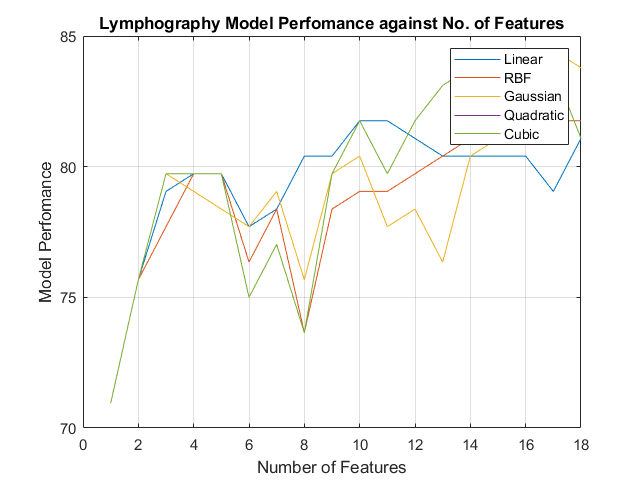

figure
plot(ave_Accuracy(:,2:6))
title('Lymphography Model Perfomance against No. of Features')
xlabel('Number of Features')
ylabel('Model Perfomance')
legend('Linear','RBF','Gaussian','Quadratic','Cubic')
grid on;

## Step 5: Model Selection: Best Hyperparameters

We now need to search for the best hyperparameters for the highest accuracy perfomance for the dataset.The following functions will be utilized to tune the SVM parameters C and Kernel function variables We use fitcsvm and train using the best features obtained from step 4. The kernel function is selected from the best perfoming Kernel in the previous step

%The best observed Kernel is Linear
template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'KernelScale', 'auto', ...
    'Standardize', true);
rng(3);
%For the bayesain optimizer we let it use the defaults but increase its Maximum Objective evaluations to 30
SVM_Model = fitcecoc(X(:,history.In(17,:)),Y,'Learners', template,...
    'OptimizeHyperparameters','auto','Coding','onevsone','HyperparameterOptimizationOptions',struct('UseParallel',true,...
    'ShowPlots',false,'MaxObjectiveEvaluations',30,'Repartition',true));

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstrain-|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              | t            |              |
|==============================================================================================================================|
|    1 |       2 | Best   |      0.4527 |     0.42853 |      0.4527 |      0.4527 |     onevsall |    0.0025451 |       551.03 |
|    2 |       2 | Accept |      0.4527 |     0.64283 |      0.4527 |      0.4527 |     onevsone |       1.3003 |      0.15726 |
|    3 |       2 | Best   |     0.14865 |     0.44654 |     0.14865 |     0.17044 |     onevsone |       632.51 |       33.728 |
|    4 |    

## Step 6: Train a SVM and Evaluate Validation Loss : Kernel linear

This step will now train the SVM using the best features selected in step 3 and the optimal hyperparameters found in step 4.

%Pass on our X and Y to the SVM classifier.
rng(3); %seeds our random generator allowing for reproducibility of results
%Box Costraint is our penalty factor C, the higher the stricter the hyperplane
constraint = 893.62;
kernelScale = SVM_Model.BinaryLearners{1}.KernelParameters.Scale;

%using a Linear kernel
template = templateSVM(...
    'BoxConstraint',constraint,...
    'KernelScale',kernelScale,...
    'KernelFunction','polynomial',...
    'Standardize', false);

%using a polynomial kernel
best_SVMModel = fitcecoc(X(:,history.In(17,:)),Y,'CVPartition',CV,'Coding','ternarycomplete');


%This averages our cross validated models loss. The lower the better the prediction
% Compute validation accuracy
SVM_ValidationAccuracy = (1 - kfoldLoss(best_SVMModel, 'LossFun', 'ClassifError'))*100

SVM_ValidationAccuracy = 83.7838

%This averages our cross validated models loss. The lower the better the prediction
bc_ModelLoss = kfoldLoss(best_SVMModel)

bc_ModelLoss = 0.1622

## Step 7: Evaluate the model's perfomance using the test set.

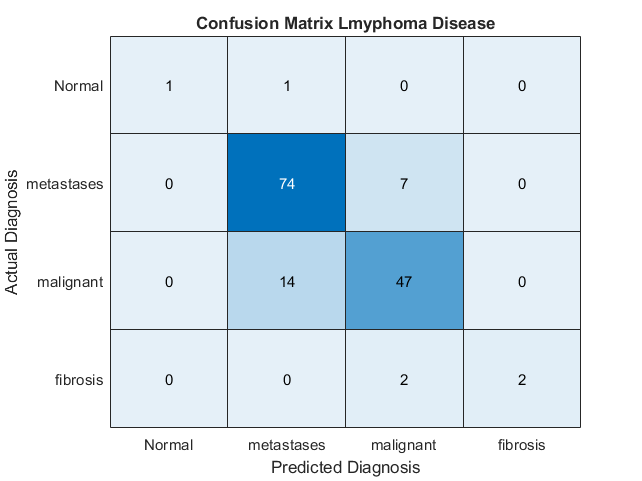

[Y_pred, validationScores] = kfoldPredict(best_SVMModel);
conMat=confusionmat(Y,Y_pred);
%Generate a Confusion Matrix
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat = heatmap(conMat,'Title','Confusion Matrix Lmyphoma Disease','YLabel','Actual Diagnosis','XLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Normal','metastases', 'malignant','fibrosis'},'YDisplayLabels',{'Normal','metastases', 'malignant','fibrosis'},'ColorbarVisible','off');

%The following functions compute the precision and F1 Score
precisionFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,2);
recallFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,1);
f1ScoresFunc = @(confusionMat) 2*(precisionFunc(confusionMat).*recallFunc(confusionMat))./(precisionFunc(confusionMat)+recallFunc(confusionMat));
meanF1Func = @(confusionMat) mean(f1ScoresFunc(confusionMat));
precision = precisionFunc(conMat)

precision =     0.5000
    0.9136
    0.7705
    0.5000


recall = recallFunc(conMat)

recall =     1.0000    0.0112    0.0179    0.5000
   74.0000    0.8315    1.3214   37.0000
   47.0000    0.5281    0.8393   23.5000
    2.0000    0.0225    0.0357    1.0000


f1Score = meanF1Func(conMat)

f1Score =     1.1969    0.3906    0.4962    1.1105
